clear
warning off
dbstop if error
tic
options=optimset("Display","off");
[kfasneg,eigenvalue]=deal(linspace(0.2,0.4,20));

a=0;
B=[linspace(0,0.49,50),linspace(0.51,2,50)]*complex(0,1);

for i = 1:length(kfasneg)
    eigenvalue(i)=dimersolver(a,kfasneg(i),40/6,B(1));
    toc
    if eigenvalue(i)>0
        break
    end
end

时间已过 0.011940 秒。
时间已过 0.012891 秒。
时间已过 0.013752 秒。
时间已过 0.014605 秒。
时间已过 0.016142 秒。
时间已过 0.017144 秒。
时间已过 0.017831 秒。
时间已过 0.018512 秒。
时间已过 0.019219 秒。
时间已过 0.019892 秒。
时间已过 0.020541 秒。
时间已过 0.021187 秒。



eigs1=zeros(1,length(B));

eigs1(1)=fsolve(@(x) dimersolver(a,x,40/6,B(1)),eigenvalue(i),options);
for i=2:length(eigs1)
    try
        eigs1(i)=fsolve(@(x) dimersolver(a,x,40/6,B(i)),eigs1(i-1),options);
        toc
       
    catch ME
        eigs1=eigs1(1:i);
        
        B=B(1:i);
        break;
        
    end
end

时间已过 0.078133 秒。
时间已过 0.090145 秒。
时间已过 0.099004 秒。
时间已过 0.105477 秒。
时间已过 0.112798 秒。
时间已过 0.119113 秒。
时间已过 0.124663 秒。
时间已过 0.130088 秒。
时间已过 0.135196 秒。
时间已过 0.140266 秒。
时间已过 0.145301 秒。
时间已过 0.150339 秒。
时间已过 0.155291 秒。
时间已过 0.160459 秒。
时间已过 0.165539 秒。
时间已过 0.170679 秒。
时间已过 0.175708 秒。
时间已过 0.181083 秒。
时间已过 0.186175 秒。
时间已过 0.191298 秒。
时间已过 0.196204 秒。
时间已过 0.210910 秒。
时间已过 0.216202 秒。
时间已过 0.221201 秒。
时间已过 0.226037 秒。
时间已过 0.231147 秒。
时间已过 0.236555 秒。
时间已过 0.241602 秒。
时间已过 0.246541 秒。
时间已过 0.251524 秒。
时间已过 0.256443 秒。
时间已过 0.261418 秒。
时间已过 0.266380 秒。
时间已过 0.271517 秒。
时间已过 0.276711 秒。
时间已过 0.281859 秒。
时间已过 0.286852 秒。
时间已过 0.291983 秒。
时间已过 0.297608 秒。
时间已过 0.303276 秒。
时间已过 0.309307 秒。
时间已过 0.325263 秒。
时间已过 0.330539 秒。
时间已过 0.335634 秒。
时间已过 0.340506 秒。
时间已过 0.346160 秒。
时间已过 0.351613 秒。
时间已过 0.356687 秒。
时间已过 0.362063 秒。
时间已过 0.367295 秒。
时间已过 0.372751 秒。
时间已过 0.377734 秒。
时间已过 0.383143 秒。
时间已过 0.388986 秒。
时间已过 0.394672 秒。
时间已过 0.399837 秒。
时间已过 0.404887 秒。
时间已过 0.409861 秒。
时间已过 0.414607 

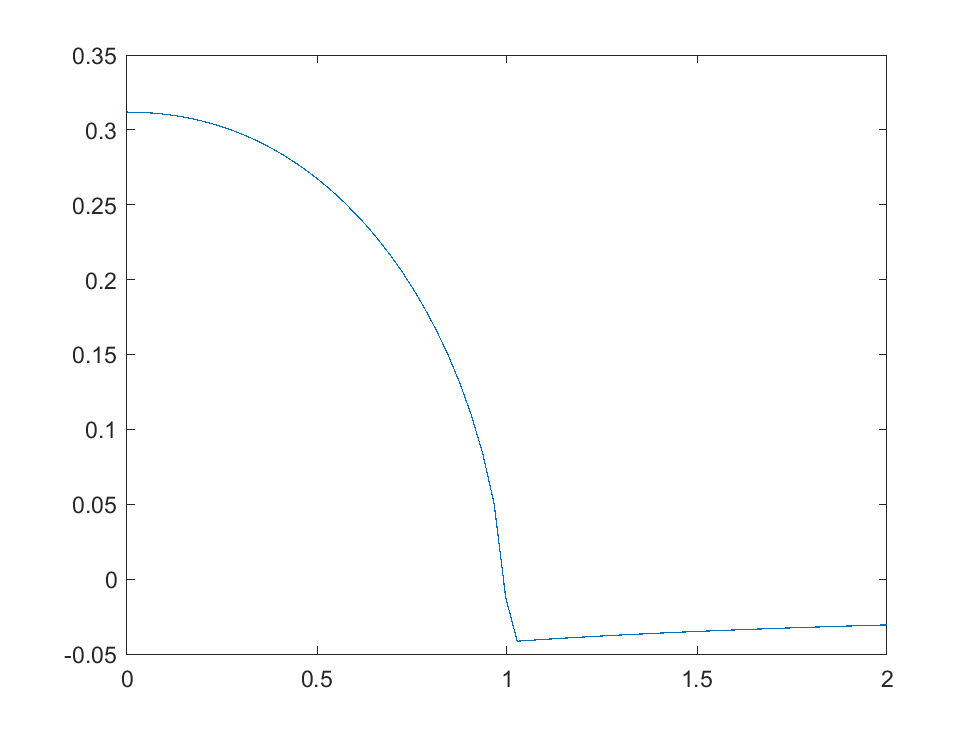

figure
plot(imag(B),eigs1)